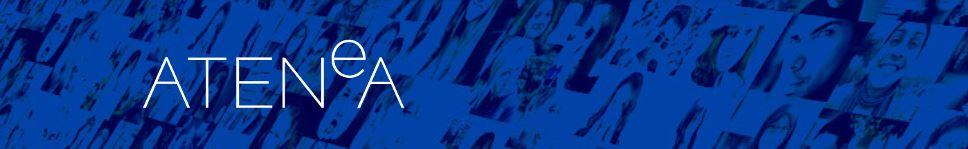

## Pràctica 1

Escriviu una funció que calculi la inversa d'una matriu $A$ d'ordre $n$:


$$\textrm{inversa}\left(A\right)$$


`(a) `El procediment és: resoldre $n$ sistemes lineals$Ax_j=e_j$, on $e_j$ és la $j$-èssima columna de la matriu identitat i la inversa de $A$ és $X$ amb columnes $x_j$. La funció ha de cridar un cop a la funció de Matlab decomposition i $n$ cops a linsolve (un per a cada columna de $X$).

`(b) `Per al joc de proves preneu matrius diferents d’ordres diversos escollides del calaix de matrius de Matlab.

`(c) `Apliqueu el mètode dos cops: primer, invertint la matriu $A$, que dóna $X$ i després, invertint $X$ que dóna $Z$; llavors una possible mesura del mètode és $\left|\left|Z-A\right|\right|$. Tabuleu aquests resultats.

`(d) `Consulteu la documentació de Matlab: [Measure the Performance of Your Code](https://es.mathworks.com/help/matlab/matlab_prog/measure-performance-of-your-program.html?searchHighlight=cputime&s_tid=srchtitle#buw2ygr), i [Techniques to Improve Performance](https://es.mathworks.com/help/matlab/matlab_prog/techniques-for-improving-performance.html?searchHighlight=Techniques%20to%20Improve%20Performance&s_tid=srchtitle). Afegiu el còmput del temps en els procediments de càlcul. Compareu el vostre temps i el temps dedicat per la funció **inv** de Matlab. Presenteu els resultats en taules. 

`(e) `Comenteu i argumenteu els resultats que s'obtenen. 

**Observació**: en cap cas cal escriure totes les matrius inverses.

#### FUNCIÓ INVERSA

% Exemple
A = [1 0 2; -1 5 0; 0 3 -9]

A =      1     0     2
    -1     5     0
     0     3    -9


Ainv = inversa(A)

Ainv =     0.8824   -0.1176    0.1961
    0.1765    0.1765    0.0392
    0.0588    0.0588   -0.0980


% Comprovació
inv(A) - Ainv

ans = 	1.0e+-16 *

         0   -0.1388         0
    0.2776    0.2776         0
    0.0694    0.0694         0


#### `JOC DE PROVES`

format
test = [5 50 500];  % testeig diferents ordres
% Inicialització
my_time = zeros(3,1);       % temps calculats amb inverse
matlab_time = zeros(3,1);   % temps calculats amb inv
res = zeros(3,1);           % ||Z-A||
R = [];
% Testeig amb matrius rand, randn i wilkinson
for i = 1:length(test)
    n = test(i);
    
    % rand
    mat = rand(n);
    tic
    X = inversa(mat);
    my_time(1) = toc;
    Z = inversa(X);
    res(1) = norm(Z-mat);   
    
    tic
    X = inv(mat);
    matlab_time(1) = toc;
    
    % randn
    mat = randn(n);
    tic
    X = inversa(mat);
    my_time(2) = toc;
    Z = inversa(X);
    res(2) = norm(Z-mat);
    
    tic
    X = inv(mat);
    matlab_time(2) = toc;
    
    % wilkinson
    mat = wilkinson(n);
    tic
    X = inversa(mat);
    my_time(3) = toc;
    Z = inversa(X);
    res(3) = norm(Z-mat);
    
    tic
    X = inv(mat);
    matlab_time(3) = toc;
    
    R = [R, my_time, matlab_time, res];
end
T = array2table(R,...
    'VariableNames',{'inversa sec (n=5)','inv sec (n=5)','||Z-A|| (n=5)', ...
    'inversa sec (n=50)','inv sec (n=50)','||Z-A|| (n=50)', ...
    'inversa sec (n=500)','inv sec (n=500)','||Z-A|| (n=500)'}, 'RowNames',{'rand','randn','wilkinson'});
% Diferencia de temps entre inversa i inv
E5 = abs(R(:,2)-R(:,1));
E50 = abs(R(:,5)-R(:,4));
E500 = abs(R(:,8)-R(:,7));
E = [E5, E50, E500];
S = array2table(E,...
    'VariableNames',{'|inversa-inv| sec (n=5)','|inversa-inv| sec (n=50)','|inversa-inv| sec (n=500)'}, ...
    'RowNames',{'rand','randn','wilkinson'});
disp(T), fprintf("\n Diferencia de temps:\n\n"), disp(S)

                 inversa sec (n=5)    inv sec (n=5)    ||Z-A|| (n=5)    inversa sec (n=50)    inv sec (n=50)    ||Z-A|| (n=50)    inversa sec (n=500)    inv sec (n=500)    ||Z-A|| (n=500)
                 _________________    _____________    _____________    __________________    ______________    ______________    ___________________    _______________    _______________

    rand              0.10059           9.43e-05        3.4642e-15           0.063419            0.011182         2.7334e-13            0.11443             0.0091303         5.2374e-11   
    randn            0.025274           4.57e-05        1.0526e-15          0.0005855          

#### COMENTARIS

A mesura que creix l'ordre de la matriu, més triga a calcular la inversa. També ens adonem que l'inv de matlab és més ràpida que la inversa implenetada, això es degut a que realitza una descomposició LU de la matriu de entrada, utilitza els resultats per formar un sistema lineal de la  qual la solució és la inversa de la matriu inv(x) i utilitza optimitzacions segons el tipus de matriu. Això ho veiem per exemple en matrius d'ordre gran com pot ser 500, on la inversa de matlab és 6 vegades més ràpida que la inversa implementada. Finalment, veiem a la taula la mesura del mètode utilitzant $\left|\left|Z-A\right|\right|$ és molt propera a cero amb moltes xifres significatives.

function X = inversa(A)
% Calcula la inversa de la matriu quadrada A

% Descomposició matriu A
dA = decomposition(A);

I = eye(size(A));   % matriu identitat
n = size(A,1);      % mida matriu
X = zeros(size(A)); % matriu inversa

% Resolució sistema lineal per a la matriu d'identitat
for j = 1:n
    b = I(:,j);
    X(:,j) = dA\b;  % linsolve(dA,b)
end
end
